area = 10.8800

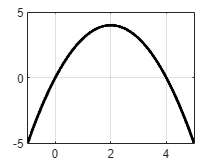

Index in position 1 is invalid. Array indices must be positive integers or logical values.

   clc
close all
clear all

iex = 2;

%% EXAMPLE 2:  Midpoint rule
if iex ==2
    % Make an example Parabola
    % y = ax^2 + bx + c
    
    % Input coefficients
    a = -1;
    b = 4;
    c = 0;
    
    % Intialize x
    x = [-1:.01:5];
    
    % Initialize function
    f = @(a,b,c,x) a*x.^2 + b*x + c;
    
    % Call the function and find value of Y at X
    y = f(a,b,c,x);
    
    % Discretize X for summation
    xmin = 0; xmax = 4;
    Nsamples = 6; % Number of points for dividing x (N-1 rectangles)
    x_sum = linspace(xmin,xmax,Nsamples);
    h = x_sum(2) - x_sum(1);
    
    % Find mid-points of x
    x_mid = conv(x_sum,[0.5 0.5],'valid');
    
    % Y- points at mid-points for summation
    y_mid = f(a,b,c,x_mid);
    

    area = 0;
    for i = 1:Nsamples-1
        area = area + h*y_mid(i);
    end
       area
       % plot
       figure
       plot(x,y,'k','LineWidth',2);
       grid on, hold on  
    
    % color area under the rectangle
    for ii = 1:length(x_sum)-1
        area([x_sum(ii) x_sum(ii+1)],[y_mid(ii) y_mid(ii)]);
    end
    
    % plot circluar markers
    for ii = 1:length(x_mid)
        plot([x_mid(ii)],[y_mid(ii)],'o','MarkerFaceColor','r','MarkerEdgeColor','k');
    end
    title(sprintf('Mid-point Rule \n %dx^2 + %dx + %d; Area = %0.2f; N = %d',a,b,c,area1,Nsamples))
end